clear all

tspan = 2014:0.1:2814;
all_results = simESM_w_soc_YJM(100, tspan,0.0);

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 109.421824 seconds.


all_results

all_results = struct with fields:
         xPvals: [8001×100 double]
         xRvals: [8001×100 double]
           catm: [8001×100 double]
            coc: [8001×100 double]
           cveg: [8001×100 double]
            cso: [8001×100 double]
              T: [8001×100 double]
         params: [1×100 struct]
        pre2014: [2141×7 double]
    blineParams: [8001×7 double]


temperature_vals = all_results.T;
bline_params_results = all_results.blineParams;

median_vals = quantile(temperature_vals', 0.5);
bot_five    = quantile(temperature_vals', 0.05);
top_five    = quantile(temperature_vals', 0.95);

clf
plot(all_results.pre2014(:,1), all_results.pre2014(:,end))
%plot(test_1751to2014(:,1), test_1751to2014(:,end))
hold on
%plot(tspan, avg_(:,end))
xlim([1900,max(tspan)])
ylim([0,8])
size(temperature_vals)

ans =         8001         100


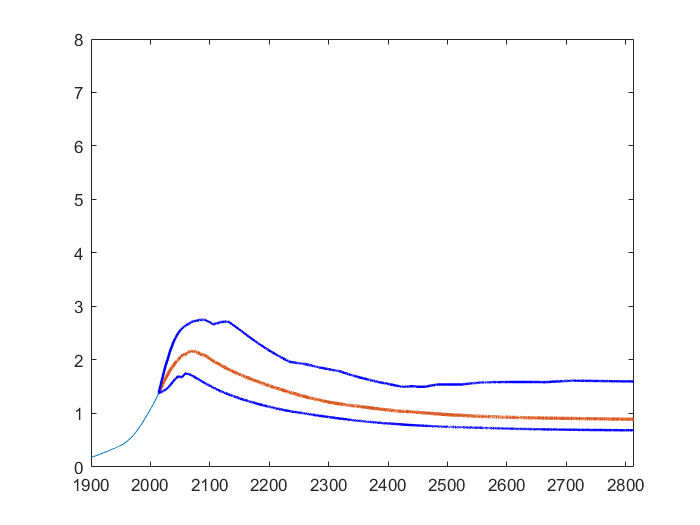


%plot(tspan, bline_params_results(:,end))
plot(tspan, median_vals, 'LineWidth', 2)
plot(tspan, top_five, 'LineWidth', 1.5, 'Color','b')
alpha(0.15);
plot(tspan, bot_five, 'LineWidth', 1.5, 'Color','b')

alpha(0.15);
%legend("pre2014","median", "top5", "bot5")

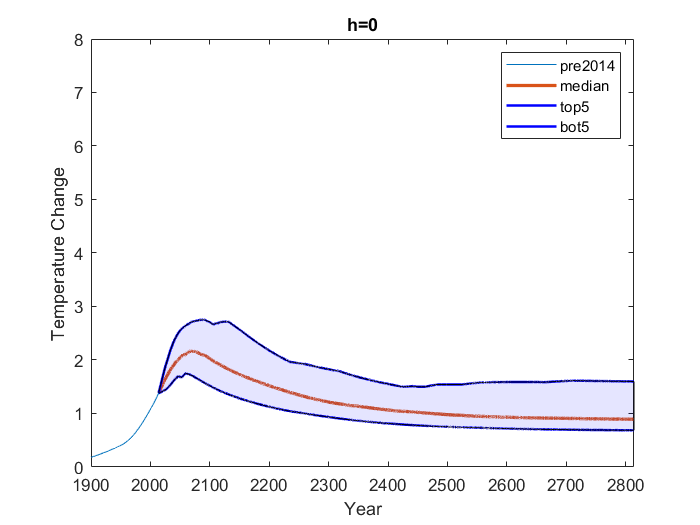

x2 = [tspan, fliplr(tspan)];
inBetween = [bot_five, fliplr(top_five)];
fill(x2, inBetween, 'b');
alpha(0.1);
xlabel('Year')
ylabel('Temperature Change')
title("h=0")
legend("pre2014","median", "top5", "bot5")

%{

    x0    = 0.05;
    kappa = 0.2;
    delta = 0.5;
    beta  = 0.5;
    t_f   = 50;
    f_max = 6;
%}

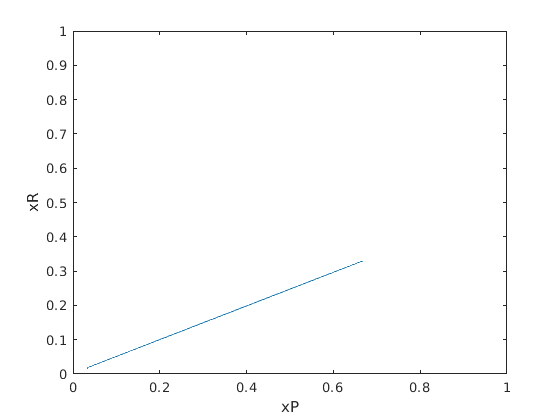

clf
plot(all_results.xPvals(:,25), all_results.xRvals(:,25))
xlabel("xP")
ylabel("xR")
ylim([0,1])
xlim([0,1])

xPvals = all_results.xPvals./(1-all_results.prop_R0);
xRvals = all_results.xRvals./(all_results.prop_R0);

median_vals_xP = quantile(xPvals', 0.5);
bot_five_xP    = quantile(xPvals', 0.05);
top_five_xP    = quantile(xPvals', 0.95);

median_vals_xR = quantile(xRvals', 0.5);
bot_five_xR    = quantile(xRvals', 0.05);
top_five_xR    = quantile(xRvals', 0.95);

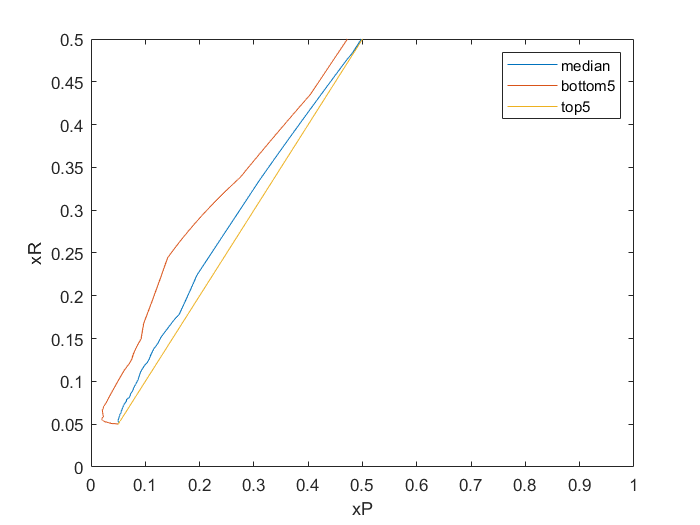

clf
plot(median_vals_xP, median_vals_xR)
hold on
plot(bot_five_xP, bot_five_xR)
plot(top_five_xP, top_five_xR)
xlabel("xP")
ylabel("xR")
ylim([0,0.5])
xlim([0,1])
legend("median", "bottom5", "top5")

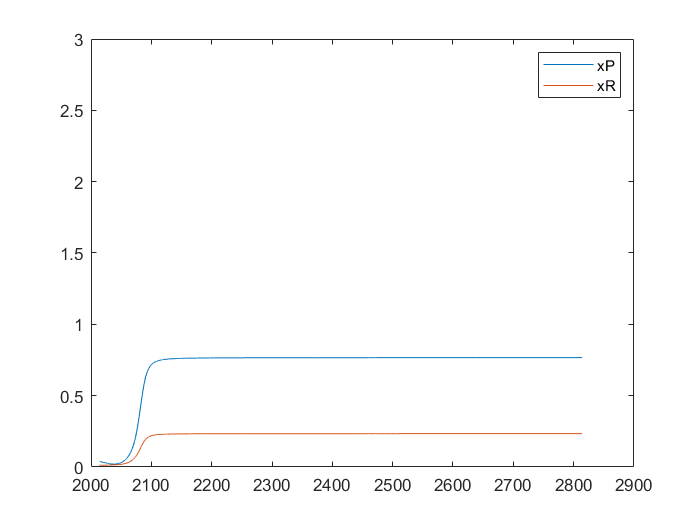

clf
plot(tspan, all_results.xPvals(:,63))
hold on
plot(tspan, all_results.xRvals(:,63))
legend("xP", "xR")
ylim([0,3])


plot(tspan, temperature_vals(:,63)-1)

Unrecognized function or variable 'temperature_vals'.

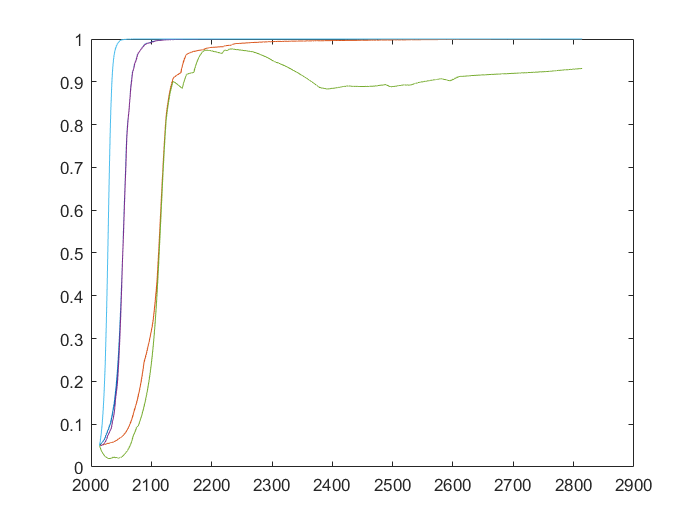

clf
plot(tspan, median_vals_xR)
hold on
plot(tspan, bot_five_xR)
plot(tspan, top_five_xR)

plot(tspan, median_vals_xP)
plot(tspan, bot_five_xP)
plot(tspan, top_five_xP)

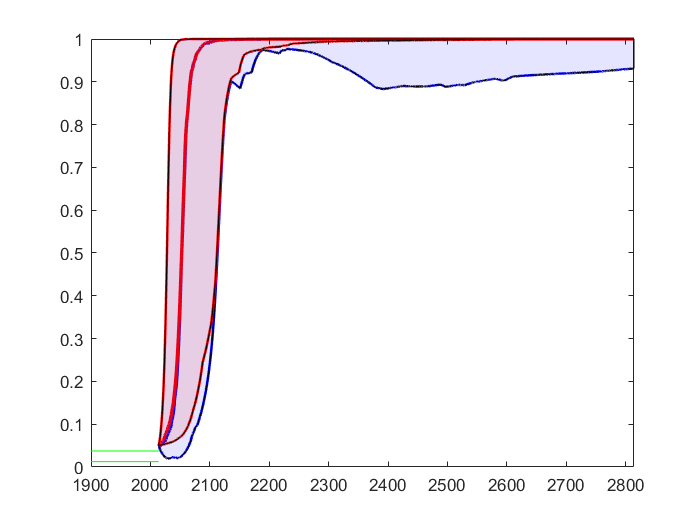

clf
len_ = size(all_results.pre2014(:,1));
zeros_ = ones((len_(1))).*(0.05*0.75);
plot(all_results.pre2014(:,1), zeros_, 'Color','g')
%plot(test_1751to2014(:,1), test_1751to2014(:,end))
hold on
%plot(tspan, avg_(:,end))
xlim([1900,max(tspan)])
ylim([0,1])
%size(temperature_vals)

%plot(tspan, bline_params_results(:,end))
plot(tspan, median_vals_xP, 'LineWidth', 2, 'Color', 'b')
plot(tspan, median_vals_xR, 'LineWidth', 2, 'Color', 'r')

plot(tspan, top_five_xP, 'LineWidth', 1.5, 'Color','b')
alpha(0.15);
plot(tspan, bot_five_xP, 'LineWidth', 1.5, 'Color','b')
alpha(0.15);
%legend("pre2014","median", "top5", "bot5")
x2 = [tspan, fliplr(tspan)];
inBetween_xP = [bot_five_xP, fliplr(top_five_xP)];
fill(x2, inBetween_xP, 'b');
alpha(0.1);

%%% Rich pop
plot(all_results.pre2014(:,1), zeros_.*(0.25/0.75), 'Color','g')
plot(tspan, top_five_xR, 'LineWidth', 1.5, 'Color','r')
alpha(0.15);
plot(tspan, bot_five_xR, 'LineWidth', 1.5, 'Color','r')
alpha(0.15);
%legend("pre2014","median", "top5", "bot5")
x2 = [tspan, fliplr(tspan)];
inBetween_xR = [bot_five_xR, fliplr(top_five_xR)];
fill(x2, inBetween_xR, 'r');
alpha(0.1);

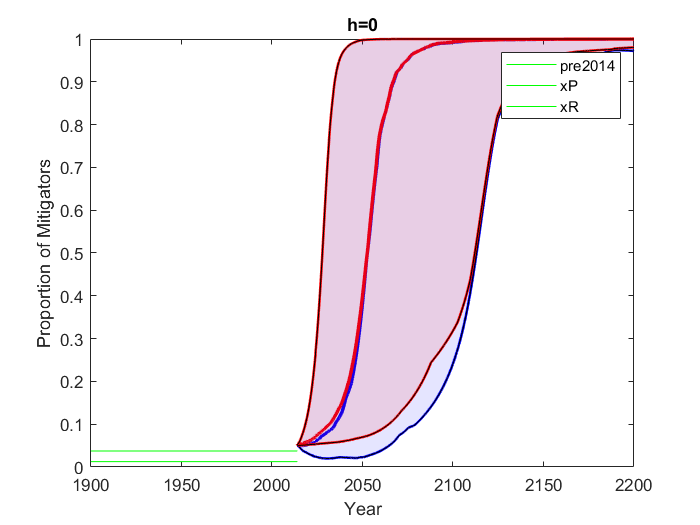

xlabel('Year')
ylabel('Proportion of Mitigators')
title("h=0")
legend("pre2014","xP", "xR")
xlim([1900,2200])

% Compute dissatisfaction
c_Pvals = all_results.params.c_P;

Reference to non-existent field 'params'.

c_Rvals = all_results.params.c_R;
omega_Rvals = all_results.params.omega_R;
omega_Pvals = all_results.params.omega_P;
I_R = max(0, omega_Rvals - exp(-(1./c_Rvals).*(temperature_vals' - 1.5)));
I_P = max(0, omega_Pvals - exp(-(1./c_Pvals).*(temperature_vals' - 1.5)));

alpha_P1vals = all_results.params.alpha_P1;
rho_ = all_results.params.prop_R0;
temp_Omega = all_results.params.Omega;
tdc = all_results.params.Td_c;
tempDis = ((rho_ - xRvals')./rho_).*(I_R - I_P);
%disp(apple)
disVals = alpha_P1vals./(1+exp( -temp_Omega.*(tempDis - tdc) ));